# Exercise 7.3 - Sampling and aliasing

## Observations

Once again, we get aliasing for the 5 kHz signal, since the sampling frequency is 8 kHz. In other words, it is less than twice that of the signal. That is not the case for the first and second signals. It is proved that the aliased frequency of the third signal is f_alias = fs - f0_3 = 8000 - 5000 = 3 kHz. That is, precisely the frequency of the second signal. By plotting their respective spectrum and listening to them, we see and hear that the resulting signal is, in fact, one and the same.

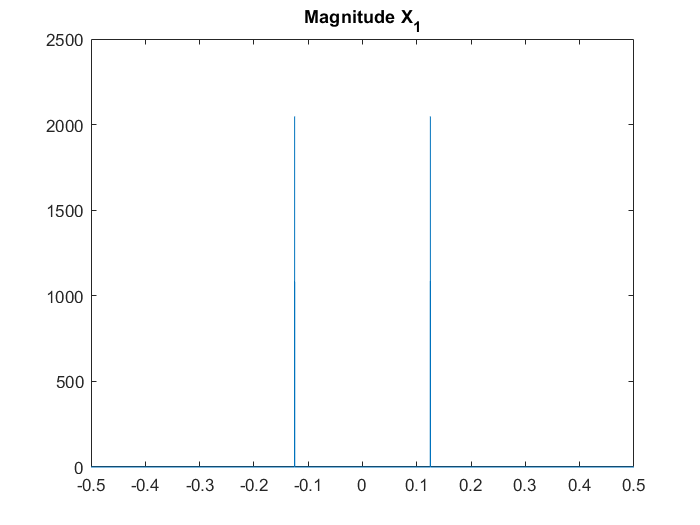

f0_1 = 1000;    % Digital frequency #1.
f0_2 = 3000;    % Digital frequency #2.
f0_3 = 5000;    % Digital frequency #3.
fs = 8000;      % Sampling frequency.

n = 0 : fs - 1;                     % Discrete time array.
n_frag = 0 : (0.0125 * fs) - 1;     % Fragment discrete time array.

% Let's define x1[n], x2[n] and x3[n].
x_1 = cos(2 * pi * f0_1 / fs * n);
x_2 = cos(2 * pi * f0_2 / fs * n);
x_3 = cos(2 * pi * f0_3 / fs * n);

% Play the generated signals.
%soundsc(x_1, fs);
soundsc(x_2, fs);
%soundsc(x_3, fs);

% Plot a small fragment of x1[n] in the discrete-time domain.
%stem(n_frag, x_1(1 : (0.0125 * fs)));

% Fourier Transform.
N = 4096;                                       % # of points.
spectrum_1 = fft(x_1, N);                       % Compute FFT.
spectrumShifted_1 = fftshift(spectrum_1);       % Shift to the origin.
spectrum_2 = fft(x_2, N);                          
spectrumShifted_2 = fftshift(spectrum_2); 
spectrum_3 = fft(x_3, N);
spectrumShifted_3 = fftshift(spectrum_3);

% Plot of the spectrum (magnitude of the FFT).
f = (0 : (N - 1)) / N - 0.5;    % OX-axis boundaries.
plot(f, abs(spectrumShifted_1)), title('Magnitude X_1');

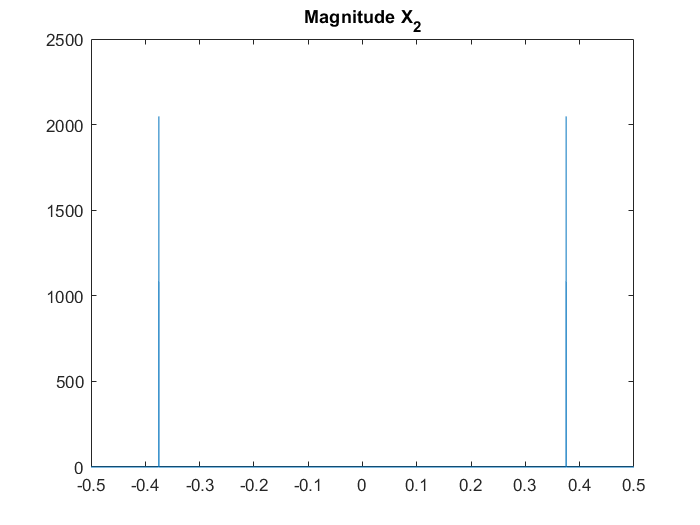

plot(f, abs(spectrumShifted_2)), title('Magnitude X_2');

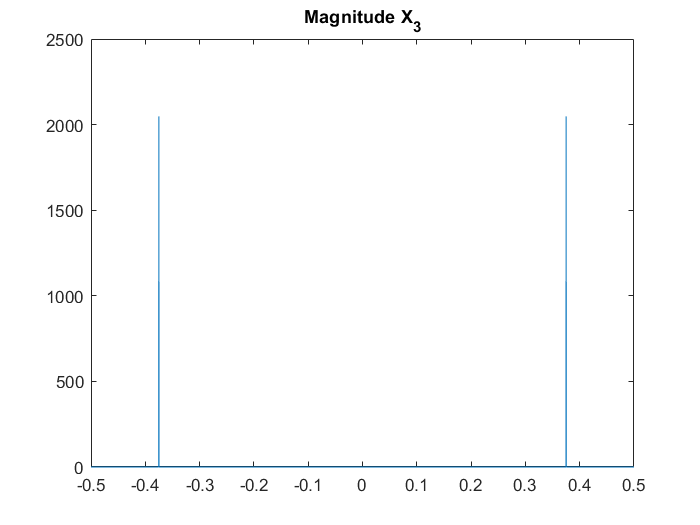

plot(f, abs(spectrumShifted_3)), title('Magnitude X_3');